## Ligevægt af bagakslen

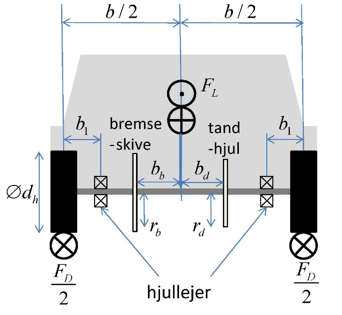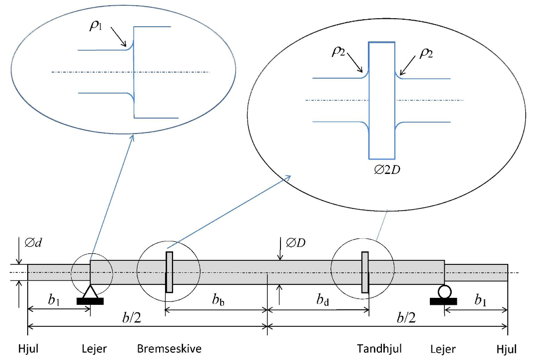

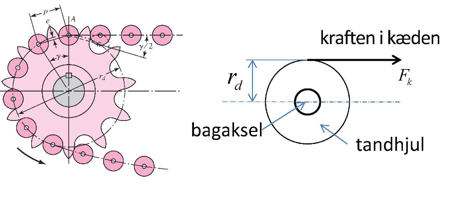

Drivningen af bagakslen foregår via en kæde og et tandhjul med radius $r_d = 80 mm$, placeret i afstanden $b_d = 100 mm$ fra køretøjets midte.

Derudover har vi

- 
$$d = 0.6 D$$


- 
$$\rho_1 = \rho_2 = 4 mm$$


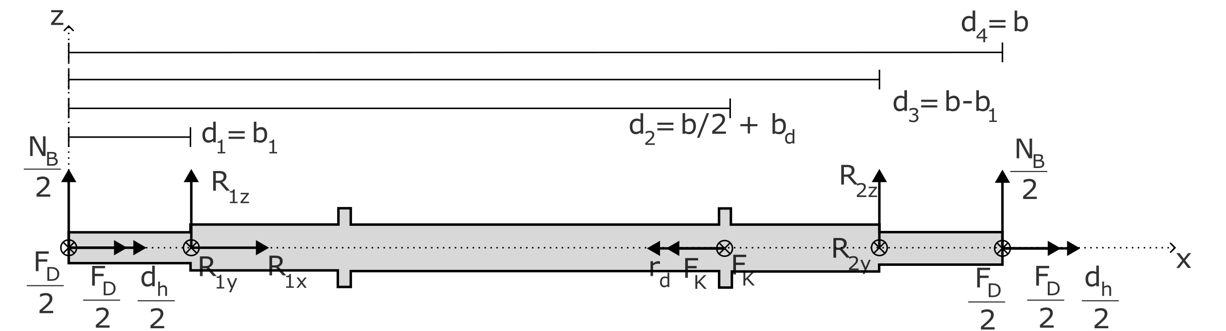

I filen bil_ligevaegt.mlx er drivkraften ved hjulene $F_D$ og normalkraften på bagakslen $N_B$ fundet. Disse deles hver især på begge hjul, hvorfor krafterne ved hvert hjul vil være hhv. $\frac{F_D}{2}$ og $\frac{N_B}{2}$. 

Vi kan finde kædekraften $F_K$ vha. en moment-ligevægt om akslens længdeakse. Hvert hjul yder en kraft på $F_D/2$ på akslen og "armen" er radiusen af hjulet $d_h/2$. Derfor er momentet fra et hjul:


$$M_{hjul} = \frac{F_D}{2} \cdot \frac{d_h}{2} = \frac{F_D d_h}{4}$$


Idet der er to hjul skal dette ganges med to:


$$M_{total} = 2 M_{hjul} = \frac{F_D d_h}{2}$$


Kæden leverer et moment på


$$M_{k\ae de} = F_k r_d$$


Momentligevægt giver da


$$M_{total} - M_{k\ae de} = 0 \iff \frac{F_D d_h}{2} - F_k r_d = 0$$


Så


$$F_k = \frac{1}{2}\frac{F_D d_h}{r_d}$$


Kraft-ligevægt i z-retningen (idet vi antager symmetri) giver


$$R_{1z} = R_{2z} = - \frac{N_B}{2}$$


Kraft-ligevægt i y-retningen giver


$$R_{1y} + R_{2y} + F_D + F_K = 0$$


Nu tager vi en momentbalance om leje 1 ($x=d_1$)


$$R_{2y} (d_3 - d_1) + F_D \left( \frac{d_4}{2} - d_1 \right) + F_K (d_2 - d_1) = 0$$



$$R_{2y} = - \frac{F_D \left( \frac{d_4}{2} - d_1 \right) + F_K (d_2 - d_1)}{d_3 - d_1}$$


Momentbalance om leje 2 ($x = d_3$) giver:


$$R_{1y} (d_3 - d_1) + F_D \left( d_3 - \frac{d_4}{2} \right) + F_K (d_3 - d_2) = 0$$



$$R_{1y} = - \frac{F_D \left( d_3 - \frac{d_4}{2} \right) + F_K (d_3 - d_2)}{d_3 - d_1}$$


clear; close all; clc;

%% bil-ligevægts-resultater
load('bil_ligevaegt.mat','bil');
F_D = bil.F_D;
N_B = bil.N_B;

%Definitioner
r_d = 0.08; %m
b_d = 0.1; %m
d_h = 0.12; %m
b = 1; %m
b_1 = 0.1; %m
b_b = 0.1; %m

%Afstande
d_1 = b_1;
d_2 = b/2 + b_d;
d_3 = b - b_1;
d_4 = b;

%Kædekraften
F_K = 0.5 * F_D * d_h / r_d;

%Reaktioner i z
R_1z = - N_B/2;
R_2z = - N_B/2;

%Reaktioner i y
R_1y = - (F_D *(d_3 - d_4/2) + F_K *(d_3 - d_2))/(d_3 - d_1);
R_2y = - (F_D *(d_4/2 - d_1) + F_K *(d_2 - d_1))/(d_3 - d_1);

%Gem resultater i en struct
aksel = struct();
aksel.F_K = F_K;
aksel.R_1z = R_1z;
aksel.R_2z = R_2z;
aksel.R_1y = R_1y;
aksel.R_2y = R_2y;

save('aksel_ligevaegt.mat','aksel');

%Output resultater
fprintf('\n=== Ligevægt for aksel ===\n');


=== Ligevægt for aksel ===


fprintf('F_K    = %.2f N\n', aksel.F_K);

F_K    = 588.23 N


fprintf('R_1y   = %.2f N\n', aksel.R_1y);

R_1y   = -612.74 N


fprintf('R_2y   = %.2f N\n', aksel.R_2y);

R_2y   = -759.80 N


fprintf('R_1z   = %.2f N\n', aksel.R_1z);

R_1z   = -672.18 N


fprintf('R_2z   = %.2f N\n', aksel.R_2z);

R_2z   = -672.18 N
